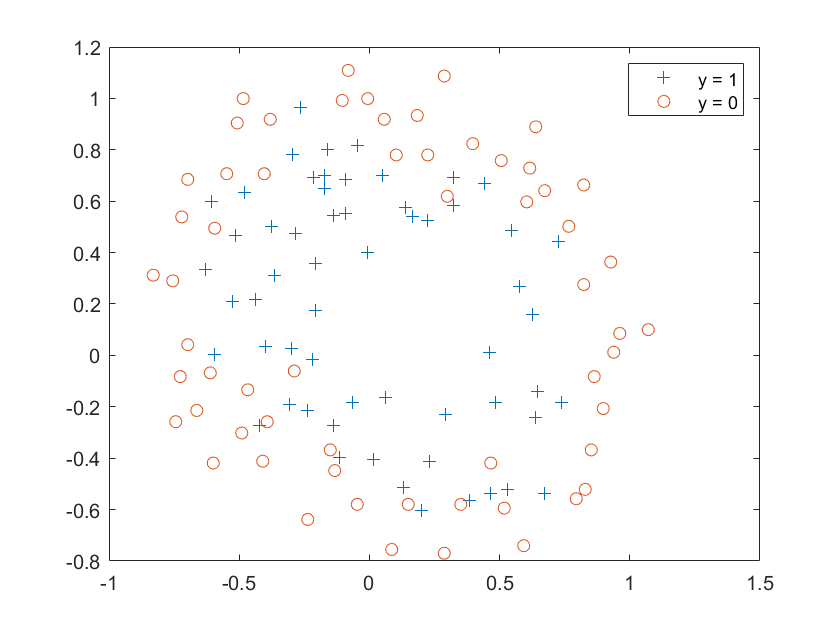

x = load('ex5Data\ex5Logx.dat');
y = load('ex5Data\ex5Logy.dat');
figure
pos = find(y);neg = find(y == 0);
plot(x(pos, 1), x(pos, 2), '+')
hold on 
plot(x(neg, 1), x(neg, 2),'o')
legend('y = 1','y = 0')
hold off;

% 为x赋值
u = x(:,1);
v = x(:,2);
xold = x;
x = map_feature(u, v)

x =     1.0000    0.0513    0.6996    0.0026    0.0359    0.4894    0.0001    0.0018    0.0251    0.3424    0.0000    0.0001    0.0013    0.0176    0.2395    0.0000    0.0000    0.0001    0.0009    0.0123    0.1675    0.0000    0.0000    0.0000    0.0000    0.0006    0.0086    0.1172
    1.0000   -0.0927    0.6849    0.0086   -0.0635    0.4691   -0.0008    0.0059   -0.0435    0.3213    0.0001   -0.0005    0.0040   -0.0298    0.2201   -0.0000    0.0001   -0.0004    0.0028   -0.0204    0.1508    0.0000   -0.0000    0.0000   -0.0003    0.0019   -0.0140    0.1033
    1.0000   -0.2137    0.6923    0.0457   -0.1479    0.4792   -0.0098    0.0316   -0.1024    0.3317    0.0021   -0.0068    0.0219   -0.0709    0.2296   -0.0004    0.0014   -0.0047    0.0152   -0.0491    0.1590    0.0001   -0.0003    0.0010   -0.0032    0.0105   -0.0340    0.1100
    1.0000   -0.3750    0.5022    0.1406   -0.1883    0.2522   -0.0527    0.0706   -0.0946    0.1266    0.0198   -0.0265    0.0355   -0.0475    0.0636   

x(1,:)'

ans =     1.0000
    0.0513
    0.6996
    0.0026
    0.0359
    0.4894
    0.0001
    0.0018
    0.0251
    0.3424


m = length(y)

m = 117

% 添加lambda
lambda1 = 0

lambda1 = 0

lambda2 = 1

lambda2 = 1

lambda3 = 10

lambda3 = 10

% h(theta, x)

% 进行训练
epoch_num = 15;
% lambda1
theta1 = zeros(28,1);
xx = 1:1:15;
yy1 = zeros(15,1);
for i = 1 : epoch_num
    loss = J(x, y, theta1, lambda1);
    yy1(i) = loss;
    a = hansen(theta1, x, lambda1);
    t = a \ Jd(x, y, theta1, lambda1);
    theta1 = theta1 - t;
end

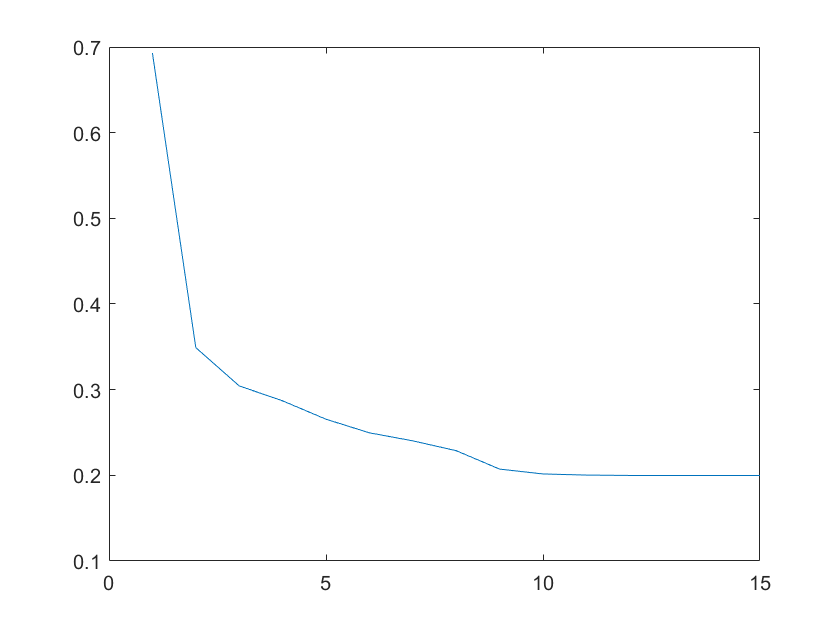

% 绘制loss曲线
plot(xx, yy1)

figure
pos = find(y);neg = find(y == 0);
plot(xold(pos, 1), xold(pos, 2), '+')
hold on ;
plot(xold(neg, 1), xold(neg, 2),'o')
legend('y = 1','y = 0');

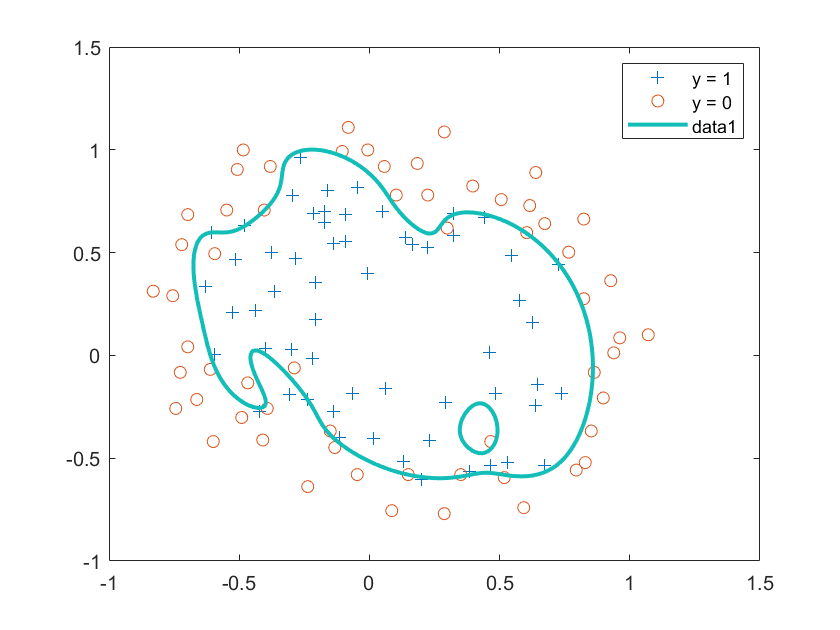


% De f ine t h e r ange s o f t h e g r i d
u = linspace ( -1, 1.5 , 200 ) ;
v = linspace ( -1, 1.5 , 200 ) ;
% I n i t i a l i z e s p ace f o r t h e v a l u e s t o be p l o t t e d
z = zeros ( length ( u ) , length ( v ) ) ;
% Ev al u a te z = t h e t a ∗x over t h e g r i d
for i = 1 : length ( u )
    for j = 1 : length ( v )
        t = map_feature( u ( i ) , v ( j ) );
% N o t ice t h e o r de r o f j , i here !
        z (i , j) = t * theta1 ;
    end
end
% Because o f t h e way t h a t c on t our p l o t t i n g works
% in Matlab , we need t o t r a n s p o s e z , or
% e l s e t h e a x i s o r i e n t a t i o n w i l l be f l i p p e d !
z = z';
% Pl o t z = 0 by s p e c i f y i n g t h e range [ 0 , 0 ]
contour(u , v , z , [0 , 0] , 'LineWidth' , 2 )
hold off;

% 训练2
% 进行训练
epoch_num = 15;
% lambda1
theta2 = zeros(28,1);
xx = 1:1:15;
yy2 = zeros(15,1);
for i = 1 : epoch_num
    loss = J(x, y, theta2, lambda2);
    yy2(i) = loss;
    a = hansen(theta2, x, lambda2);
    t = a \ Jd(x, y, theta2, lambda2);
    theta2 = theta2 - t;
end

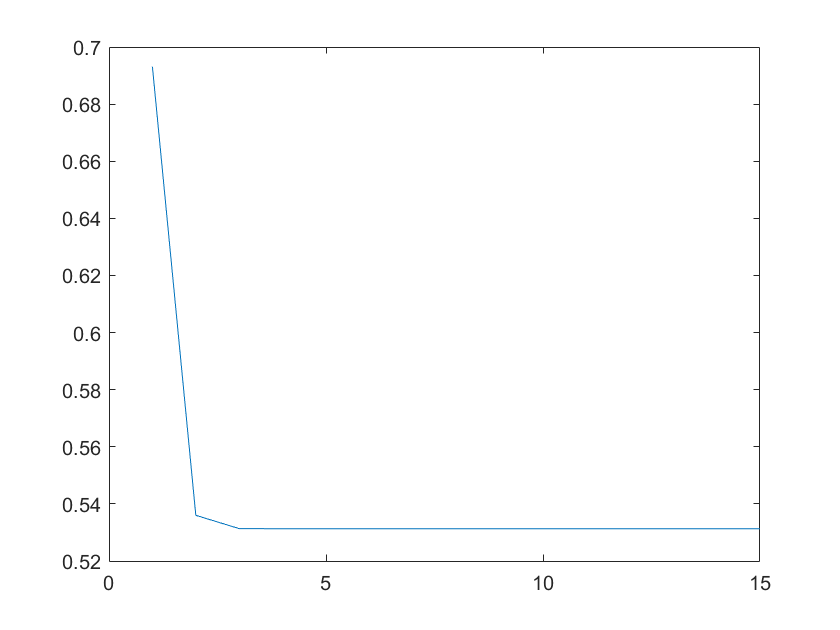

% 绘制loss曲线
plot(xx, yy2)

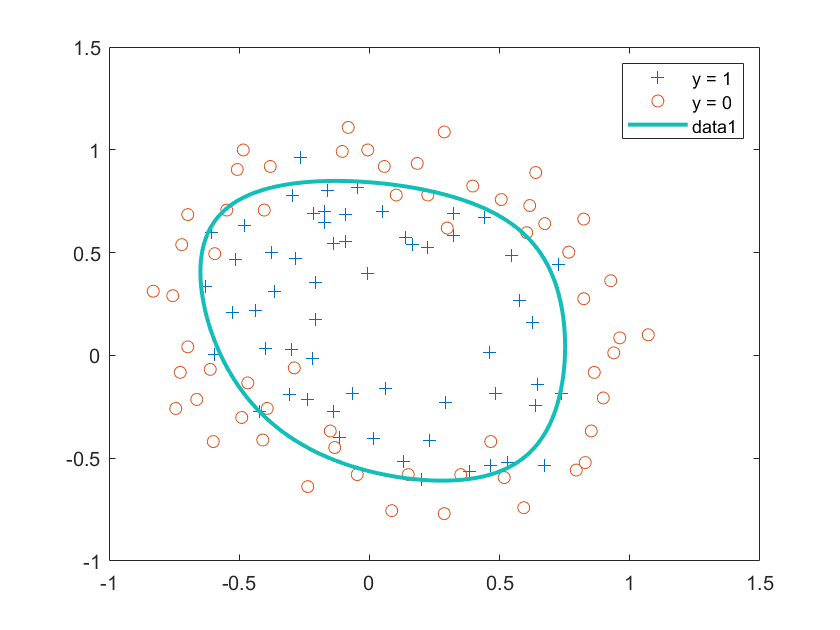

figure
pos = find(y);neg = find(y == 0);
plot(xold(pos, 1), xold(pos, 2), '+')
hold on ;
plot(xold(neg, 1), xold(neg, 2),'o')
legend('y = 1','y = 0');
% De f ine t h e r ange s o f t h e g r i d
u = linspace ( -1, 1.5 , 200 ) ;
v = linspace ( -1, 1.5 , 200 ) ;
% I n i t i a l i z e s p ace f o r t h e v a l u e s t o be p l o t t e d
z = zeros ( length ( u ) , length ( v ) ) ;
% Ev al u a te z = t h e t a ∗x over t h e g r i d
for i = 1 : length ( u )
    for j = 1 : length ( v )
% N o t ice t h e o r de r o f j , i here !
z ( i , j ) = map_feature( u ( i ) , v ( j ) ) * theta2 ;
    end
end
% Because o f t h e way t h a t c on t our p l o t t i n g works
% in Matlab , we need t o t r a n s p o s e z , or
% e l s e t h e a x i s o r i e n t a t i o n w i l l be f l i p p e d !
z = z';
% Pl o t z = 0 by s p e c i f y i n g t h e range [ 0 , 0 ]
contour ( u , v , z , [ 0 , 0 ] , 'LineWidth' , 2 )
hold off;

% 训练3

% 进行训练
epoch_num = 15;
% lambda1
theta3 = zeros(28,1);
xx = 1:1:15;
yy3 = zeros(15,1);
for i = 1 : epoch_num
    loss = J(x, y, theta3, lambda3);
    yy3(i) = loss;
    a = hansen(theta3, x, lambda3);
    t = a \ Jd(x, y, theta3, lambda3);
    theta3 = theta3 - t;
end

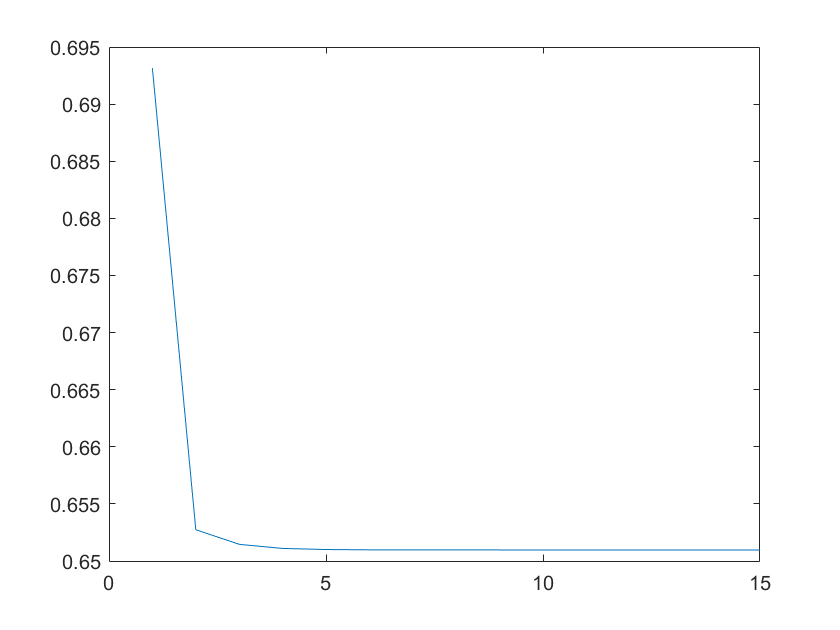

% 绘制loss曲线
plot(xx, yy3)

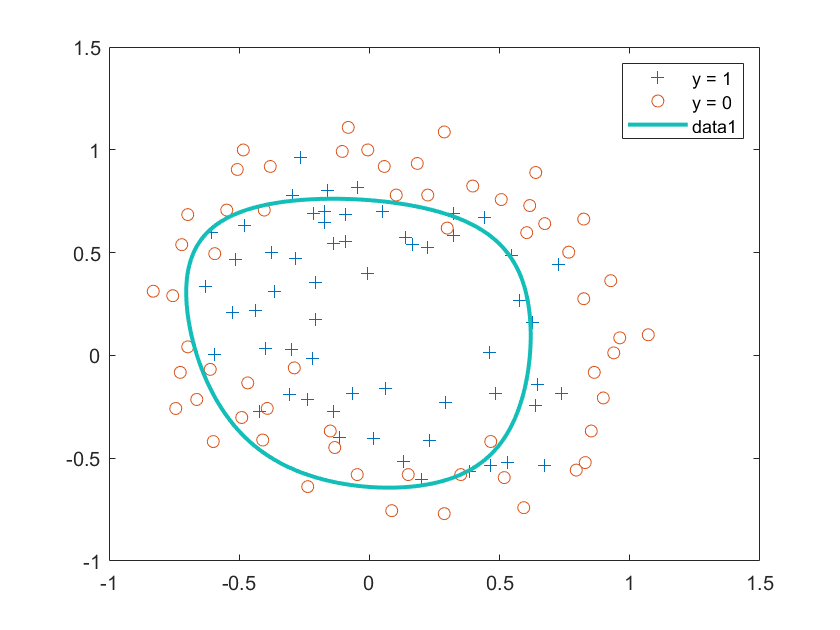

figure
pos = find(y);neg = find(y == 0);
plot(xold(pos, 1), xold(pos, 2), '+')
hold on ;
plot(xold(neg, 1), xold(neg, 2),'o')
legend('y = 1','y = 0');
% De f ine t h e r ange s o f t h e g r i d
u = linspace ( -1, 1.5 , 200 ) ;
v = linspace ( -1, 1.5 , 200 ) ;
% I n i t i a l i z e s p ace f o r t h e v a l u e s t o be p l o t t e d
z = zeros ( length ( u ) , length ( v ) ) ;
% Ev al u a te z = t h e t a ∗x over t h e g r i d
for i = 1 : length ( u )
    for j = 1 : length ( v )
% N o t ice t h e o r de r o f j , i here !
z ( i , j ) = map_feature( u ( i ) , v ( j ) ) * theta3 ;
    end
end
% Because o f t h e way t h a t c on t our p l o t t i n g works
% in Matlab , we need t o t r a n s p o s e z , or
% e l s e t h e a x i s o r i e n t a t i o n w i l l be f l i p p e d !
z = z';
% Pl o t z = 0 by s p e c i f y i n g t h e range [ 0 , 0 ]
contour ( u , v , z , [ 0 , 0 ] , 'LineWidth' , 2 )

% 对比不同的theta
theta1_l2 = norm(theta1)

theta1_l2 = 7.1727e+03

theta2_l2 = norm(theta2)

theta2_l2 = 4.0346

theta3_l2 = norm(theta3)

theta3_l2 = 0.8402